grid = gen_grid();
corClassC = correct_classify_circle(grid);
corClassD = correct_classify_triangle(grid);
corClassS = correct_classify_star(grid);

[c_cost_full, c_error_full] = give_costs_of_networks(cirkel_netwerken_full,grid,corClassC);
[c_cost_batch750, c_error_batch750] = give_costs_of_networks(cirkel_netwerken_batch,grid,corClassC);
[c_cost_batch500, c_error_batch500] = give_costs_of_networks(cirkel_netwerken_batch500,grid,corClassC);
[c_cost_rbatch750, c_error_rbatch750] = give_costs_of_networks(cirkel_netwerken_rbatch750,grid,corClassC);
[c_cost_rbatch500, c_error_rbatch500] = give_costs_of_networks(cirkel_netwerken_rbatch500,grid,corClassC);

[d_cost_full, d_error_full] = give_costs_of_networks(driehoek_netwerken_full,grid,corClassD);
[d_cost_batch750, d_error_batch750] = give_costs_of_networks(driehoek_netwerken_batch,grid,corClassD);
[d_cost_batch500, d_error_batch500] = give_costs_of_networks(driehoek_netwerken_batch500,grid,corClassD);
[d_cost_rbatch750, d_error_rbatch750] = give_costs_of_networks(driehoek_netwerken_rbatch750,grid,corClassD);
[d_cost_rbatch500, d_error_rbatch500] = give_costs_of_networks(driehoek_netwerken_rbatch500,grid,corClassD);

[s_cost_full, s_error_full] = give_costs_of_networks(ster_netwerken_full,grid,corClassS);
[s_cost_batch750, s_error_batch750] = give_costs_of_networks(ster_netwerken_batch,grid,corClassS);
[s_cost_batch500, s_error_batch500] = give_costs_of_networks(ster_netwerken_batch500,grid,corClassS);
[s_cost_rbatch750, s_error_rbatch750] = give_costs_of_networks(ster_netwerken_rbatch750,grid,corClassS);
[s_cost_rbatch500, s_error_rbatch500] = give_costs_of_networks(ster_netwerken_rbatch500,grid,corClassS);


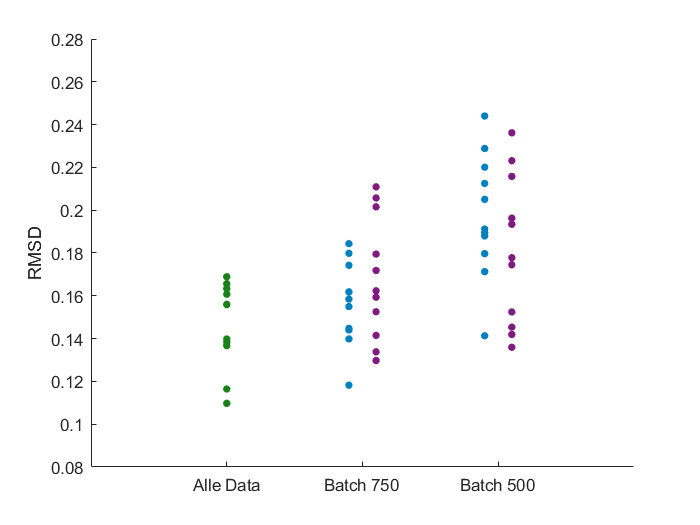


plot_costs_per_shape(c_cost_full, c_cost_batch750, c_cost_rbatch750, c_cost_batch500, c_cost_rbatch500)

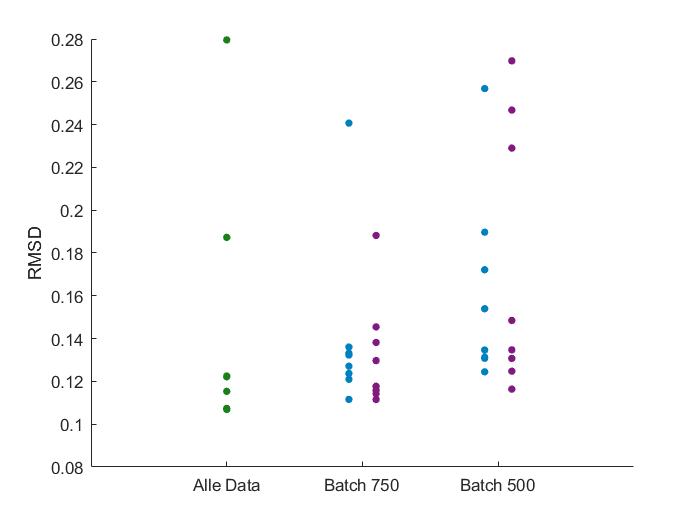


plot_costs_per_shape(d_cost_full, d_cost_batch750, d_cost_rbatch750, d_cost_batch500, d_cost_rbatch500)

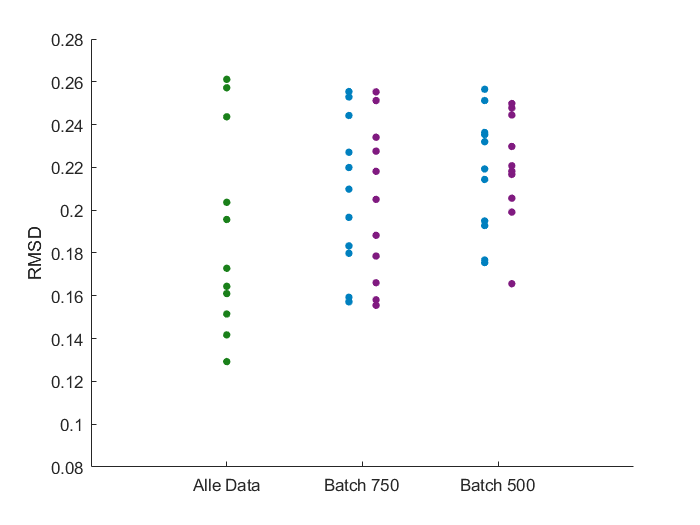


plot_costs_per_shape(s_cost_full, s_cost_batch750, s_cost_rbatch750, s_cost_batch500, s_cost_rbatch500)

%MH proces
[cirkel_init, data, grid] = init_circle_network_and_data(2000);
plot_normal_net_classification(cirkel_init, grid)

networks = metropolis_hasting(cirkel_init, 1000, 1000, 0.07, 20, data, 2000, 'FULL');
resultNetworks = random_sample(networks, 1000);
plot_Bayesian_Network_classification(resultNetworks,grid)

temp = {networks metropolis_hasting(cirkel_init, 29000, 0, 0.07, 20, data, 2000, 'FULL')};
networks = horzcat(temp{:});
resultNetworks = random_sample(networks, 30000);
plot_Bayesian_Network_classification(resultNetworks,grid)

[driehoek_init, data, grid] = init_driehoek_network_and_data(10000);
plot_normal_net_classification(driehoek_init, grid)

networks = metropolis_hasting(driehoek_init, 1000, 1000, 0.05, 20, data, 2000, 'FULL');
resultNetworks = random_sample(networks, 1000);
plot_Bayesian_Network_classification(resultNetworks,grid)

temp = {networks metropolis_hasting(driehoek_init, 29000, 0, 0.05, 20, data, 2000, 'FULL')};
networks = horzcat(temp{:});
resultNetworks = random_sample(networks, 30000);
plot_Bayesian_Network_classification(resultNetworks,grid)

[ster_init, data, grid] = init_ster_network_and_data(5000);
plot_normal_net_classification(ster_init, grid)

networks = metropolis_hasting(ster_init, 1000, 1000, 0.04, 20, data, 2000, 'FULL');
resultNetworks = random_sample(networks, 1000);
plot_Bayesian_Network_classification(resultNetworks,grid)

temp = {networks metropolis_hasting(ster_init, 29000, 0, 0.04, 20, data, 2000, 'FULL')};
networks = horzcat(temp{:});
resultNetworks = random_sample(networks, 30000);
plot_Bayesian_Network_classification(resultNetworks,grid)

for i = 1:length(ster_netwerken_rbatch500)
    plot_Bayesian_Network_classification(ster_netwerken_full{i}, grid)
    title("Ster Full")

    plot_Bayesian_Network_classification(ster_netwerken_rbatch500{i},grid)
    title("Ster R_Batch_500")
end


function plot_costs_per_shape(full, batch750, rbatch750, batch500, rbatch500)

figure
hold on
xlim([0,4])
ylim([0.08,0.28])
ylabel("RMSD")
set(gca,'XTick',1:1:3);
xticklabels(["Alle Data","Batch 750","Batch 500"])


for i = 1:length(full)
    scatter([1],[full(i)],20,[0.1, 0.5, 0.1],"filled")
    scatter([1.9 2.9],[batch750(i) batch500(i)],20,[0, 0.5, 0.75],"filled")
    scatter([2.1 3.1], [rbatch750(i) rbatch500(i)],20,[0.5, 0.1, 0.5],"filled")
end

%legend("All Data", "Fixed Batch", "Random Batch",'Location','northwest','NumColumns',3)

end

%%%

function plot_error_per_shape(full, batch750, rbatch750, batch500, rbatch500)
figure
hold on
xlim([0,4])
%ylim([0,0.5])

xticklabels(["","","All Data","","Batch 750","","Batch 500"])


for i = 1:length(full)
    scatter([1],[full(i)],20,[0.1, 0.5, 0.1],"filled")
    scatter([2 3],[batch750(i) batch500(i)],20,[0, 0.5, 0.75],"filled")
    scatter([2 3], [rbatch750(i) rbatch500(i)],20,[0.5, 0.1, 0.5],"filled")
end

legend("All data", "Fixed Batch", "Random Batch",'Location','northwest','NumColumns',3)

end


%%%

function [cost_array, error_array] = give_costs_of_networks(networks_array, grid, corClass)

cost_array = [];
error_array = [];

for i = 1:length(networks_array)
    [cost, error] = give_cost_of_Bayesian_Network(networks_array{i}, grid, corClass);
    cost_array = [cost_array cost];
    error_array = [error_array error];
end

end

%%%

function [total_error, error_count] = give_cost_of_Bayesian_Network(network, grid, corClass)

total_error = 0;
error_count = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network);
    if probs(1) >= probs(2)
        confidence = probs(1);
        if corClass{c} == "A"
            error = (confidence - 1)^2;
        else
            error = (confidence)^2;
            error_count = error_count + 1;
        end
        
    else
        confidence = probs(2);
        if corClass{c} == "B"
            error = (confidence - 1)^2;
        else
            error = (confidence)^2;
            error_count = error_count + 1;
        end
    end
    total_error = total_error + error;
    
end

total_error = sqrt(total_error/length(grid));
error_count = error_count/length(grid);

end

%%%

function plot_normal_net_classification(trained_net, grid)
XA = {};
YA = {};
XB = {};
YB = {};

for i = 1: length(grid)
    x = [grid(1,i); grid(2,i)];
    a = classify(x, trained_net);
    if a(1) >= a(2)
        XA = [XA, grid(1,i)];
        YA = [YA, grid(2,i)]; 
    else
        XB = [XB, grid(1,i)];
        YB = [YB, grid(2,i)];
        
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);



figure



hold on
axis([0 1 0 1])
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')

%Shape plot
x_tot = linspace (0.1625,0.8375);
        x1 = linspace (0.1625,0.5);
        x2 = linspace (0.5,0.8375);
        y1 = (0*x_tot) + 0.725;
        y2 = -2*x1 + 1.05;
        y3 = 2*x2 - 0.95;
        y4 = (0*x_tot) + 0.275;
        y5 = 2*x1 - 0.05;
        y6 = -2*x2 + 1.95;
        plot(x_tot,y1,'black','LineWidth',2);
        plot(x1,y2,'black','LineWidth',2);
        plot(x2,y3,'black','LineWidth',2);
        plot(x_tot,y4,'black','LineWidth',2);
        plot(x1,y5,'black','LineWidth',2);
        plot(x2,y6,'black','LineWidth',2);

set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])

hold off
end

%%%

function plot_Bayesian_Network_classification(network_input, grid)
class_vec = [];
colorvector = [];
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, network_input);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    colorvector = [colorvector; (base + r + g)];
end


XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network_input);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

figure
hold on
axis([0 1 0 1])
set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')

%Shape plot
x_tot = linspace (0.1625,0.8375);
        x1 = linspace (0.1625,0.5);
        x2 = linspace (0.5,0.8375);
        y1 = (0*x_tot) + 0.725;
        y2 = -2*x1 + 1.05;
        y3 = 2*x2 - 0.95;
        y4 = (0*x_tot) + 0.275;
        y5 = 2*x1 - 0.05;
        y6 = -2*x2 + 1.95;
        plot(x_tot,y1,'black','LineWidth',2);
        plot(x1,y2,'black','LineWidth',2);
        plot(x2,y3,'black','LineWidth',2);
        plot(x_tot,y4,'black','LineWidth',2);
        plot(x1,y5,'black','LineWidth',2);
        plot(x2,y6,'black','LineWidth',2);

    
hold off

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,colorvector,'filled','s')

%Shape plot
x_tot = linspace (0.1625,0.8375);
        x1 = linspace (0.1625,0.5);
        x2 = linspace (0.5,0.8375);
        y1 = (0*x_tot) + 0.725;
        y2 = -2*x1 + 1.05;
        y3 = 2*x2 - 0.95;
        y4 = (0*x_tot) + 0.275;
        y5 = 2*x1 - 0.05;
        y6 = -2*x2 + 1.95;
        plot(x_tot,y1,'black','LineWidth',2);
        plot(x1,y2,'black','LineWidth',2);
        plot(x2,y3,'black','LineWidth',2);
        plot(x_tot,y4,'black','LineWidth',2);
        plot(x1,y5,'black','LineWidth',2);
        plot(x2,y6,'black','LineWidth',2);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off

end

%%%

function [cirkel_init, data, grid] = init_circle_network_and_data(seed)
grid = gen_grid();
corClass = correct_classify_circle(grid);

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Cirkel");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
cirkel_init = NN_gen([2 5 2],"normal", model_params, seed );
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,cirkel_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while percent < 0.8
    cirkel_init = train_net(cirkel_init, data, 0.35, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,cirkel_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end
        percent = cor_counter/length(grid);
    end
end
end

%%%

function sample = random_sample(network_input, N)

sample = cell(1,200);
indexes = randperm(N,200);
for ind = 1:length(indexes)
    sample{1,ind} = network_input{1,indexes(ind)};
end
end

function [driehoek_init, data, grid] = init_driehoek_network_and_data(seed)
grid = gen_grid();
corClass = correct_classify_triangle(grid);
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Driehoek");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
driehoek_init = NN_gen([2 4 3 2],"normal", model_params, seed );
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,driehoek_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while percent < 0.8
    driehoek_init = train_net(driehoek_init, data, 0.5, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,driehoek_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end
        percent = cor_counter/length(grid);
    end
end
end

function [ster_init, data, grid] = init_ster_network_and_data(seed)
grid = gen_grid();
corClass = correct_classify_triangle(grid);
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Ster");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
ster_init = NN_gen([2 7 5 3 2],"normal", model_params, seed);
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,ster_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while (percent < 0.9 && iter < 1000)
    ster_init = train_net(ster_init, data, 0.25, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,ster_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end   
    end
    percent = cor_counter/length(grid);
end
end
